# Live testing script

clearvars

## Initialise parameters

*TODO - set up number sliders within researched limits for the parameters*

### Time parameters

*TODO - investigate matlab timeseries data type*

time_step = 0.5; % seconds
simulation_time = 1; % 24h00 format
simulation_time = simulation_time * 3600; % seconds
starting_time = 0; % 24h00 format
if starting_time == 24
    starting_time = 0;
end
starting_time = starting_time * 3600; % seconds

### Vascular system parameters

**Arterial blood**

arterial_SpO2 = 0.98; %
arterial_glucose = 4; % mmol/L
arterial_insulin = 10; % mU/L

**Venous blood**

*Initialise to the same as arterial*

venous_SpO2 = 0.98; %
venous_glucose = arterial_glucose; % mmol/L
venous_insulin = arterial_insulin; % mU/L

### **Gut parameters**

gut_SpO2 = 0.4; %
gut_glucose = 5; % mmol/L
gut_flowrate = 500; % ml/min

### **Pancreas parameters**

pancreas_SpO2 = 0.4; %
pancreas_glucose = 5; % mmol/L
pancreas_flowrate = 500; % ml/min

### **Muscle parameters**

muscle_SpO2 = 0.4; %
muscle_glucose = 5; % mmol/L
muscle_flowrate = 500; % ml/min

### **Liver parameters**

liver_SpO2 = 0.4; %
liver_glucose = 5; % mmol/L
liver_flowrate = 500; % ml/min

### **Kidney parameters**

kidney_SpO2 = 0.4; %
kidney_glucose = 5; % mmol/L
kidney_flowrate = 500; % ml/min

### **Lung parameters**

lung_SpO2 = 0.4; %
lung_glucose = 5; % mmol/L
lung_flowrate = 500; % ml/min

### **Brain parameters**

brain_SpO2 = 0.4; %
brain_glucose = 5; % mmol/L
brain_flowrate = 500; % ml/min

### **Heart parameters**

heart_SpO2 = 0.4; %
heart_glucose = 5; % mmol/L
heart_flowrate = 500; % ml/min


## Initialise objects

VascularSystem = VascularSystem(starting_time, time_step, arterial_SpO2, arterial_glucose, arterial_insulin, venous_SpO2, venous_glucose, venous_insulin);
Gut = Gut(starting_time, time_step, gut_SpO2, gut_glucose, gut_flowrate);
Pancreas = Pancreas(starting_time, time_step, pancreas_SpO2, pancreas_glucose, pancreas_flowrate);
Muscle = Muscle(starting_time, time_step, muscle_SpO2, muscle_glucose, muscle_flowrate);
Liver = Liver(starting_time, time_step, liver_SpO2, liver_glucose, liver_flowrate);
Kidney = Kidney(starting_time, time_step, kidney_SpO2, kidney_glucose, kidney_flowrate);
Lung = Lung(starting_time, time_step, lung_SpO2, lung_glucose, lung_flowrate);
Brain = Brain(starting_time, time_step, brain_SpO2, brain_glucose, brain_flowrate);
Heart = Heart(starting_time, time_step, heart_SpO2, heart_glucose, heart_flowrate);


### Create graphing storage vectors

time_vector = zeros(1,simulation_time/time_step);
arterial_SpO2_vector = zeros(1,simulation_time/time_step);
arterial_glucose_vector = zeros(1,simulation_time/time_step);
arterial_insulin_vector = zeros(1,simulation_time/time_step);
venous_SpO2_vector = zeros(1,simulation_time/time_step);
venous_glucose_vector = zeros(1,simulation_time/time_step);
venous_insulin_vector = zeros(1,simulation_time/time_step);  
gut_SpO2_vector = zeros(1,simulation_time/time_step);
gut_glucose_vector = zeros(1,simulation_time/time_step);
pancreas_SpO2_vector = zeros(1,simulation_time/time_step);
pancreas_glucose_vector = zeros(1,simulation_time/time_step);
muscle_SpO2_vector = zeros(1,simulation_time/time_step);
muscle_glucose_vector = zeros(1,simulation_time/time_step);
liver_SpO2_vector = zeros(1,simulation_time/time_step);
liver_glucose_vector = zeros(1,simulation_time/time_step);
kidney_SpO2_vector = zeros(1,simulation_time/time_step);
kidney_glucose_vector = zeros(1,simulation_time/time_step);
lung_SpO2_vector = zeros(1,simulation_time/time_step);
lung_glucose_vector = zeros(1,simulation_time/time_step);
brain_SpO2_vector = zeros(1,simulation_time/time_step);
brain_glucose_vector = zeros(1,simulation_time/time_step);
heart_SpO2_vector = zeros(1,simulation_time/time_step);
heart_glucose_vector = zeros(1,simulation_time/time_step);


## Run simulation

for i = 0:time_step:simulation_time-time_step
    % calculate new objects
    [Gut, VascularSystem] = gut_calc(Gut, VascularSystem);
    [Pancreas, VascularSystem] = pancreas_calc(Pancreas, VascularSystem);
    [Muscle, VascularSystem] = muscle_calc(Muscle, VascularSystem);
    [Liver, VascularSystem] = liver_calc(Liver, VascularSystem);
    [Kidney, VascularSystem] = kidney_calc(Kidney, VascularSystem);
    [Brain, VascularSystem] = brain_calc(Brain, VascularSystem);
    [Heart, VascularSystem] = heart_calc(Heart, VascularSystem);
    [Lung, VascularSystem] = lung_calc(Lung, VascularSystem); % must go last, lung_calc probably needs to work differently to the others

    % store values
    % subsystems
    time_vector(i/time_step+1) = Gut.time;
    gut_SpO2_vector(i/time_step+1) = Gut.gut_SpO2;
    gut_glucose_vector(i/time_step+1) = Gut.gut_glucose;
    pancreas_SpO2_vector(i/time_step+1) = Pancreas.pancreas_SpO2;
    pancreas_glucose_vector(i/time_step+1) = Pancreas.pancreas_glucose;
    muscle_SpO2_vector(i/time_step+1) = Muscle.muscle_SpO2;
    muscle_glucose_vector(i/time_step+1) = Muscle.muscle_glucose;
    liver_SpO2_vector(i/time_step+1) = Liver.liver_SpO2;
    liver_glucose_vector(i/time_step+1) = Liver.liver_glucose;
    kidney_SpO2_vector(i/time_step+1) = Kidney.kidney_SpO2;
    kidney_glucose_vector(i/time_step+1) = Kidney.kidney_glucose;
    lung_SpO2_vector(i/time_step+1) = Lung.lung_SpO2;
    lung_glucose_vector(i/time_step+1) = Lung.lung_glucose;
    brain_SpO2_vector(i/time_step+1) = Brain.brain_SpO2;
    brain_glucose_vector(i/time_step+1) = Brain.brain_glucose;
    heart_SpO2_vector(i/time_step+1) = Heart.heart_SpO2;
    heart_glucose_vector(i/time_step+1) = Heart.heart_glucose;
    % vascular system
    arterial_SpO2_vector(i/time_step+1) = VascularSystem.arterial_SpO2;
    arterial_glucose_vector(i/time_step+1) = VascularSystem.arterial_glucose;
    arterial_insulin_vector(i/time_step+1) = VascularSystem.arterial_insulin;
    venous_SpO2_vector(i/time_step+1) = VascularSystem.venous_SpO2;
    venous_glucose_vector(i/time_step+1) = VascularSystem.venous_glucose;
    venous_insulin_vector(i/time_step+1) = VascularSystem.venous_insulin;
end
% time vector conversion to 24h00 format
time_vector = time_vector / 3600;

## Plot results

### Arterial graph

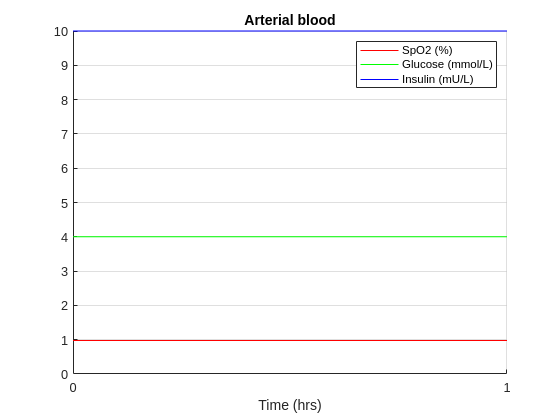

figure(1)
hold on
plot(time_vector,arterial_SpO2_vector,'r')
plot(time_vector,arterial_glucose_vector,'g')
plot(time_vector,arterial_insulin_vector,'b')
hold off
grid on
title('Arterial blood')
xlabel('Time (hrs)')
legend('SpO2 (%)','Glucose (mmol/L)','Insulin (mU/L)')
xlim([0, simulation_time/3600])
xticks(0:1:simulation_time/3600)

### SpO2 graph

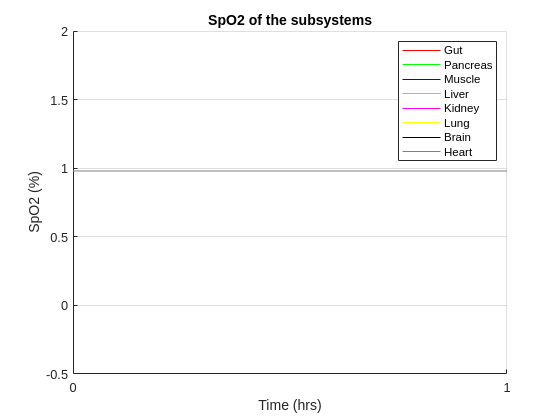

figure(2)
hold on
plot(time_vector,gut_SpO2_vector,'r')
plot(time_vector,pancreas_SpO2_vector,'g')
plot(time_vector,muscle_SpO2_vector,'b')
plot(time_vector,liver_SpO2_vector,'c')
plot(time_vector,kidney_SpO2_vector,'m')
plot(time_vector,lung_SpO2_vector,'y')
plot(time_vector,brain_SpO2_vector,'k')
plot(time_vector,heart_SpO2_vector,'Color',[0.5 0.5 0.5])
hold off
grid on
title('SpO2 of the subsystems')
xlabel('Time (hrs)')
ylabel('SpO2 (%)')
legend('Gut','Pancreas','Muscle','Liver','Kidney','Lung','Brain','Heart')
xlim([0, simulation_time/3600])
xticks(0:1:simulation_time/3600)

### Glucose graph

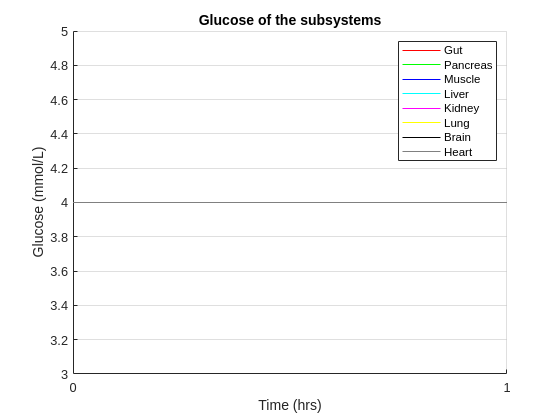

figure(3)
hold on
plot(time_vector,gut_glucose_vector,'r')
plot(time_vector,pancreas_glucose_vector,'g')
plot(time_vector,muscle_glucose_vector,'b')
plot(time_vector,liver_glucose_vector,'c')
plot(time_vector,kidney_glucose_vector,'m')
plot(time_vector,lung_glucose_vector,'y')
plot(time_vector,brain_glucose_vector,'k')
plot(time_vector,heart_glucose_vector,'Color',[0.5 0.5 0.5])
hold off
grid on
title('Glucose of the subsystems')
xlabel('Time (hrs)')
ylabel('Glucose (mmol/L)')
legend('Gut','Pancreas','Muscle','Liver','Kidney','Lung','Brain','Heart')
xlim([0, simulation_time/3600])
xticks(0:1:simulation_time/3600)